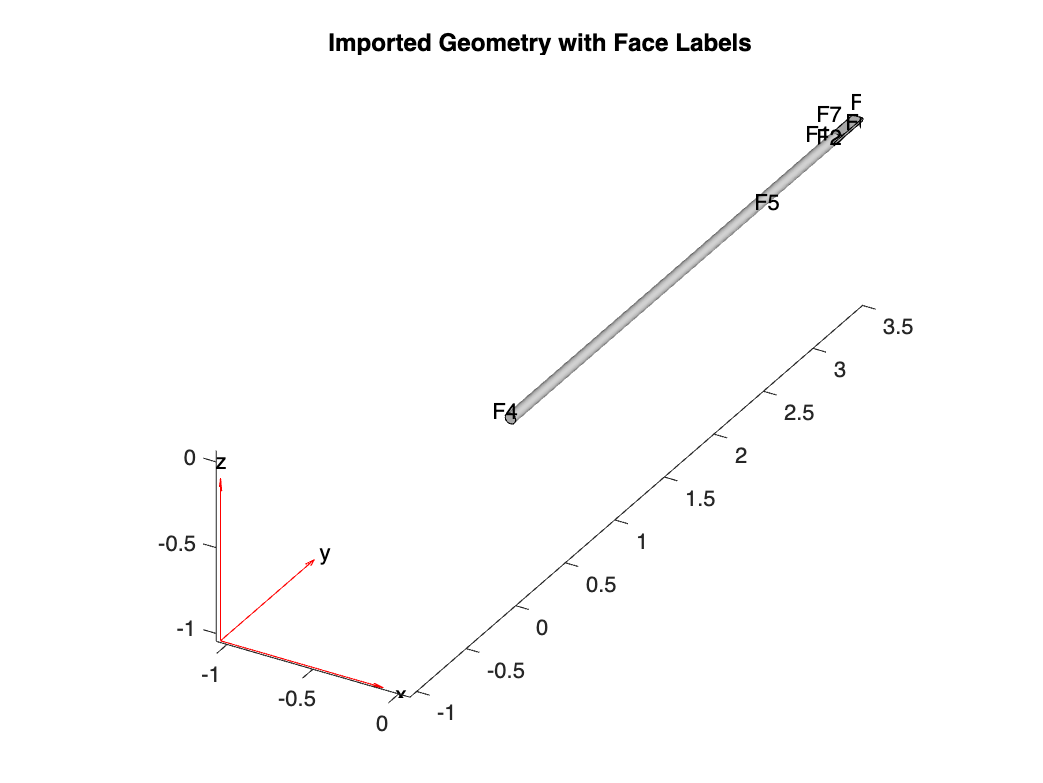

% Thermal Analysis of Shaft from STL File
% Assumes metric dimensions and uses PDE Toolbox

% Load STL geometry
model = createpde('thermal','transient');
importGeometry(model,'electrode_MATLAB_test.STL'); % Replace with your STL filename
model.Geometry = scale(model.Geometry, 0.0254); % scales stl file from SI -> metric


% Visualize geometry
figure;
pdegplot(model,'FaceLabels','on');
title('Imported Geometry with Face Labels');

% Define material properties (example: steel)
thermalProperties(model, ...
    'ThermalConductivity', 45, ...      % W/(m·K)
    'MassDensity', 7850, ...            % kg/m³
    'SpecificHeat', 470);               % J/(kg·K)

% Initial temperature
thermalIC(model,25); % Initial temperature in °C

% Apply heat to one face (e.g., face 3)
thermalBC(model,'Face',4,'HeatFlux',1e5); % W/m²

% Apply convective cooling to other faces
coolingFaces = [1 2 4 5 6 7]; % Replace with actual face IDs
thermalBC(model,'Face',coolingFaces,'ConvectionCoefficient',25,'AmbientTemperature',25);

% Mesh generation
generateMesh(model,'Hmax',0.005); % Adjust mesh size as needed


% Time settings
tlist = 0:10:600; % Simulate for 10 minutes in 10s steps

% Solve
result = solve(model,tlist);

% Plot temperature at final time
figure;
pdeplot3D(model,'ColorMapData',result.Temperature(:,end));
title('Temperature Distribution at Final Time');

% Estimate energy to heat tip to 200 °C
% Assume tip is a small region (e.g., face 6)
tipNodes = findNodes(model.Mesh,'region','Face',6);
tipTemp = result.Temperature(tipNodes,end);
avgTemp = mean(tipTemp);

% Energy = mass * specific heat * ΔT
% Estimate volume of tip region
tipVolume = 1e-6; % m³ (example)
mass = 7850 * tipVolume;
deltaT = 200 - 25;
energy = mass * 470 * deltaT;

fprintf('Estimated energy to heat tip to 200 °C: %.2f J\n', energy);
